# **TASK_03:**    Analyse the Simulation results for the quilibrium of a 3 Force Body system

Consider the system shown below.  We have a quadrilateral steel plate suspended from a support frame.  The steel plate is acted on by two spring tensions $F_{1\;} \;,F_2$, and its own weight $W$.  The points of application of these three forces are at the centres of the holes A and B and at the body’s centre of mass G, as shown in the figure below. The system is planar, that is all forces lie in one plane.

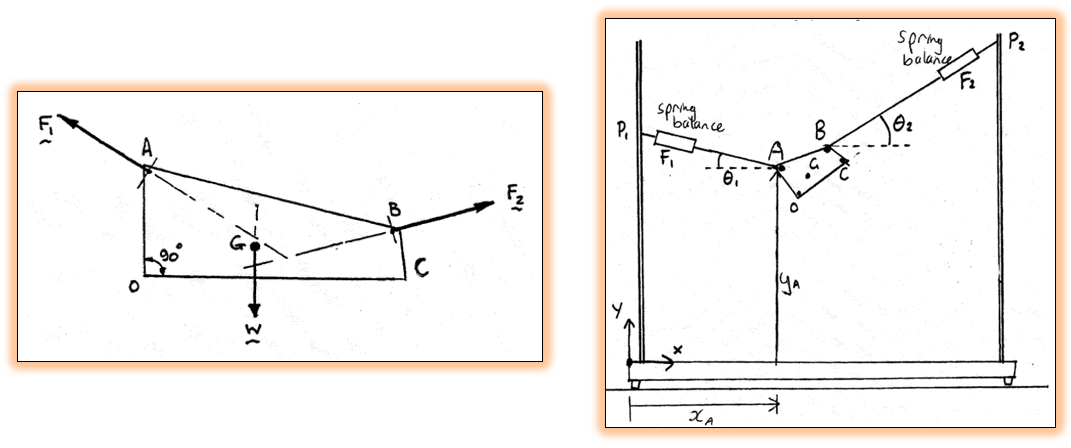

## Overview:

In this script we will

- Load in the time series data that we logged from our Simuliunk simulation

- Show that when a body is in equilibrium the vector sum of the forces acting on it must always add to zero.

- Establish a relationship between the lines of actions of the forces acting on a three-force body

## Prerequisites:

Before starting this task, it is expected that:

- You have already run the script [`TASK_01_model_parameters.mlx`](matlab: edit TASK_01_model_parameters.mlx)

- You have already run the Simulink model - see file [`TASK_02_explore_model.mlx`](matlab:  edit TASK_02_explore_the_model)

 **NOTE:**  If you have completed TASK_01 and TASK_02, your BASE MATLAB workspace should look like this:

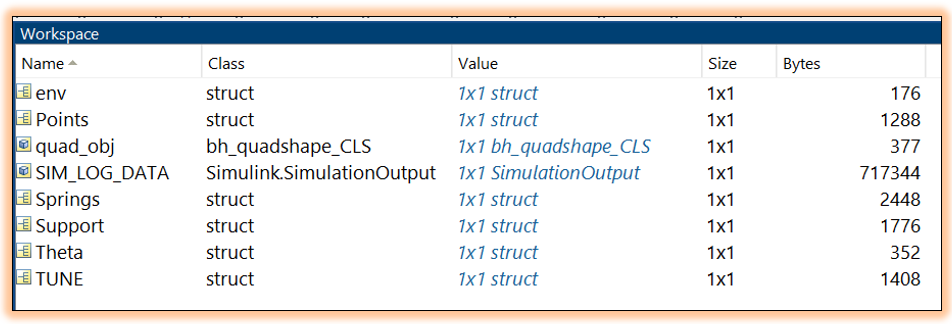

## Instructions:

- Browse each section of this MATLAB script

- If you encounter this icon  there will be a task that you must complete (eg: writing some MATLAB code OR interacting with slider bars, dropboxes etc)

- ***Sometimes*** at the end of a section you'll see this icon 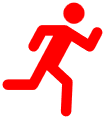, AND there will be a button to click on - When you click the button it will execute the code just in this section. You ***MUST*** click this button before advancing to the next section.

- If you see this icon  it means there's a question you're being asked to ponder.

## Explore the simulation data logged by our SCOPE block

Recall from [`TASK_02_explore_the_model.mlx`](matlab:  edit TASK_02_explore_the_model)   we ran our Simulink model and inspected a SCOPE block:

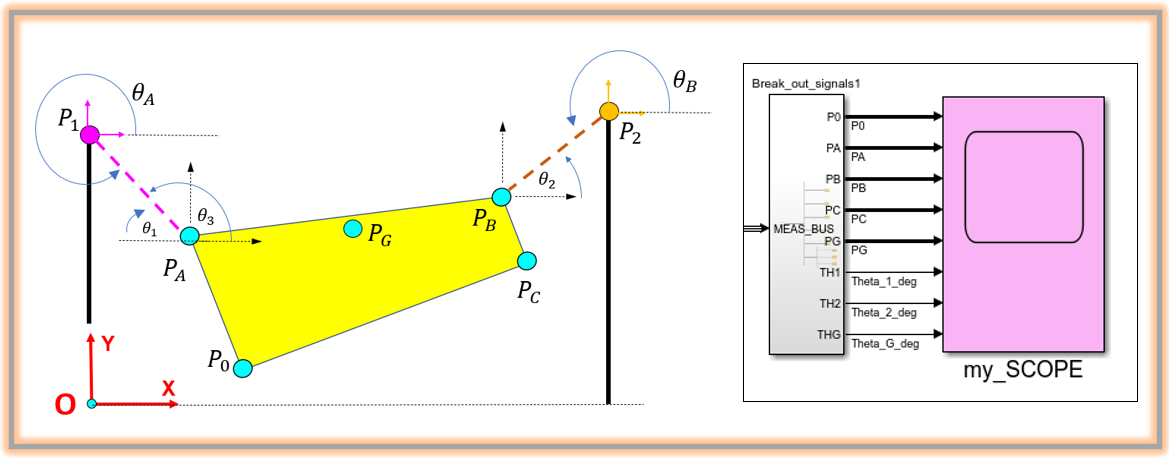

We've actually logged the timeseries data being displayed in that scope block, to our MATLAB Workspace.  All of the timeseries data is embedded in the variable named `SIM_LOG_DATA`  

So ?  - So, let's first extract the logged timeseries data out of the `SIM_LOG_DATA `variable and put it into a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))) - tables just make it so much easier to manipulate and access the data

### Create a table of our Logged Simulation data

DATA_tab = table();

The $x,y$ data for point $P_0$

DATA_tab.time       = SIM_LOG_DATA.my_MEAS.get("P0").Values.Time;
DATA_tab.PZERO_X    = SIM_LOG_DATA.my_MEAS.get("P0").Values.Data(:,1);
DATA_tab.PZERO_Y    = SIM_LOG_DATA.my_MEAS.get("P0").Values.Data(:,2);

The $x,y$ data for point $P_A$

DATA_tab.PA_X       = SIM_LOG_DATA.my_MEAS.get("PA").Values.Data(:,1);
DATA_tab.PA_Y       = SIM_LOG_DATA.my_MEAS.get("PA").Values.Data(:,2);

The $x,y$ data for point $P_B$

DATA_tab.PB_X       = SIM_LOG_DATA.my_MEAS.get("PB").Values.Data(:,1);
DATA_tab.PB_Y       = SIM_LOG_DATA.my_MEAS.get("PB").Values.Data(:,2);

The $x,y$ data for point $P_C$

DATA_tab.PC_X       = SIM_LOG_DATA.my_MEAS.get("PC").Values.Data(:,1);
DATA_tab.PC_Y       = SIM_LOG_DATA.my_MEAS.get("PC").Values.Data(:,2);

The $x,y$ data for point $P_G$

DATA_tab.PG_X       = SIM_LOG_DATA.my_MEAS.get("PG").Values.Data(:,1);
DATA_tab.PG_Y       = SIM_LOG_DATA.my_MEAS.get("PG").Values.Data(:,2);

The data for $\theta_1 \;,\theta_2 \;,\theta_G$

DATA_tab.theta1_deg = SIM_LOG_DATA.my_MEAS.get("Theta_1_deg").Values.Data;
DATA_tab.theta2_deg = SIM_LOG_DATA.my_MEAS.get("Theta_2_deg").Values.Data;
DATA_tab.thetaG_deg = SIM_LOG_DATA.my_MEAS.get("Theta_G_deg").Values.Data;

 **NOTE:**  we can access the data in the table using the following syntax:

-     `DATA_tab.PZERO_X  `

- `  DATA_tab.PB_Y`

-     etc

 Now Run this section by clicking the button below

## Plot our Simulation results:    PART_1 -  $P_0 \;,P_A ,P_B ,P_C ,P_G$

Let's explore the timeseries data that we've logged from our simulation:

Select a Point (e.g.: $P_0 \;,P_A ,P_B ,P_C ,P_G$) from the dropbox below and let's plot it's timeseries data :

tmp_id   = "PB";

 Inspect the $\textrm{time}\;\textrm{vs}\;\mathit{\mathbf{X}}$ and $\textrm{time}\;\textrm{vs}\;\mathit{\mathbf{Y}}$ plots and confirm that the point has reached a "steady state" position (i.e.: it's $X,Y$ values are no longer changing .... *or at least not changing by very much !*)

tmp_t    = DATA_tab.time;
tmp_X    = DATA_tab{:,tmp_id + "_X"};
tmp_Y    = DATA_tab{:,tmp_id + "_Y"};

figure;
   subplot(2,1,1); 
        plot(tmp_t, tmp_X, '-r.');
            xlabel("time (secs)");  
            ylabel("X (m)"); 
            legend("X-co-ord of point", "Location", "best");  
            grid("on"); axis("tight");
   subplot(2,1,2); 
        plot(tmp_t, tmp_Y, '-r.');
            xlabel("time (secs)");  
            ylabel("Y (m)"); 
            legend("Y-co-ord of point", "Location", "best")
            grid("on"); axis("tight");
   sgtitle("Trajectory of point: "+tmp_id);      

And what does the X-Y path that the point travelled look like ?

figure;
   plot(tmp_X, tmp_Y,"-b.");
        grid("on");  axis("tight");
        xlabel("X (m)");  ylabel("Y (m)"); 
        title("The X-Y path travelled by the point "+tmp_id) 

## Plot our Simulation results:    PART_2 -  $\theta_1 \;,\theta_2 \;,\theta_G$

Let's explore the timeseries data that we've logged from our simulation:

Select an angle (e.g.: $\theta_1 \;,\theta_2 \;,\theta_G$) from the dropbox below and let's plot it's timeseries data :

tmp_id    = "theta2";
tmp_t     = DATA_tab.time;
tmp_theta = DATA_tab{:,tmp_id + "_deg"};

 Inspect the $\textrm{time}\;\textrm{vs}\;\theta$ plot and confirm that the angle has reached a "steady state" position (i.e.: it's value is no longer changing .... *or at least not changing by very much !*)

figure;
   plot(tmp_t, tmp_theta, '-k.');
        xlabel("time (secs)");  
        ylabel("theta (deg)"); 
        title(tmp_id+" versus time");
        legend(tmp_id,"Location", "best");  
        grid("on"); axis("tight");

## Extract the STEADY STATE values from our simulation measurements

Next, let's extract the final steady state values for the following:

- The $\left(x,y\right)$ values for the points $P_0 \;,P_A ,P_B ,P_C ,P_G$

- The angles (degrees) for $\theta_1 \;,\theta_2 \;,\theta_G$

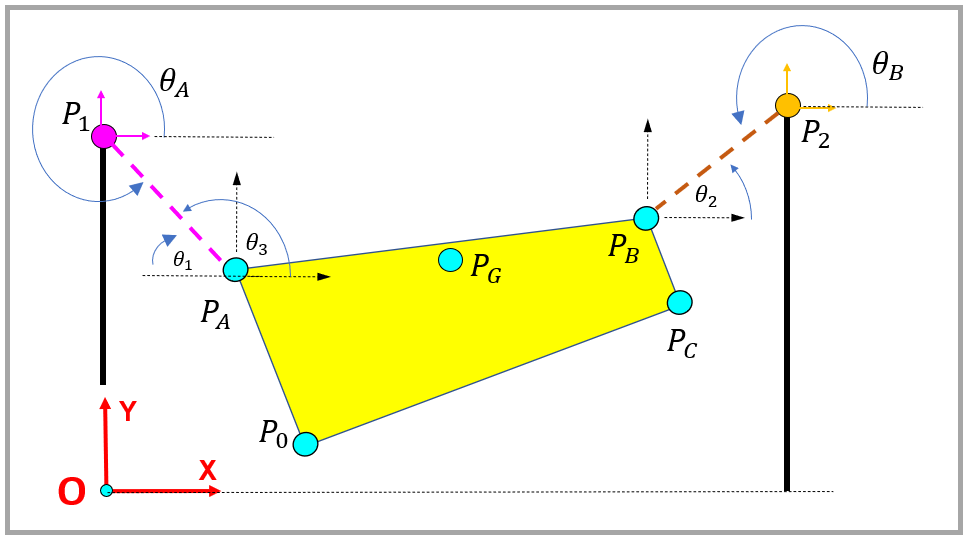

Extract the $\left(x,y\right)$ steady state values for the points $P_0 \;,P_A ,P_B ,P_C ,P_G$

Final_rel2_W.PZERO      = [DATA_tab.PZERO_X(end) ,  DATA_tab.PZERO_Y(end)];
Final_rel2_W.PA         = [DATA_tab.PA_X(end)    ,  DATA_tab.PA_Y(end)];
Final_rel2_W.PB         = [DATA_tab.PB_X(end)    ,  DATA_tab.PB_Y(end)];
Final_rel2_W.PC         = [DATA_tab.PC_X(end)    ,  DATA_tab.PC_Y(end)];
Final_rel2_W.PG         = [DATA_tab.PG_X(end)    ,  DATA_tab.PG_Y(end)];

Similarly extract the final values for $\theta_1 \;,\theta_2 \;,\theta_G$:

Final_rel2_W.theta1_deg = DATA_tab.theta1_deg(end);
Final_rel2_W.theta2_deg = DATA_tab.theta2_deg(end);
Final_rel2_W.thetaG_deg = DATA_tab.thetaG_deg(end);

And we can compute the final value for $\theta_3$

Final_rel2_W.theta3_deg = 180 - Final_rel2_W.theta1_deg;

 So what've we got so far ?

disp(Final_rel2_W)

 Now Run this section by clicking the button below

 In your Simulink model, **open the DASHBOARD subsystem** and observe the final $\left(x,y\right)$ co-ordinate values  for points $P_0 \;,P_A \;,P_B \;,P_C \;,P_G$  displayed in the LIGHT blue display blocks.  Also, observe the final values for $\theta_1 \;,\theta_2 \;,\theta_G$ displayed in the LIGHT blue display blocks.   ***Are these (LIGHT blue display blocks) values, the same as what we have just computed above ?***

## Compute the final spring displacements and Forces $F_1$ and $F_2$

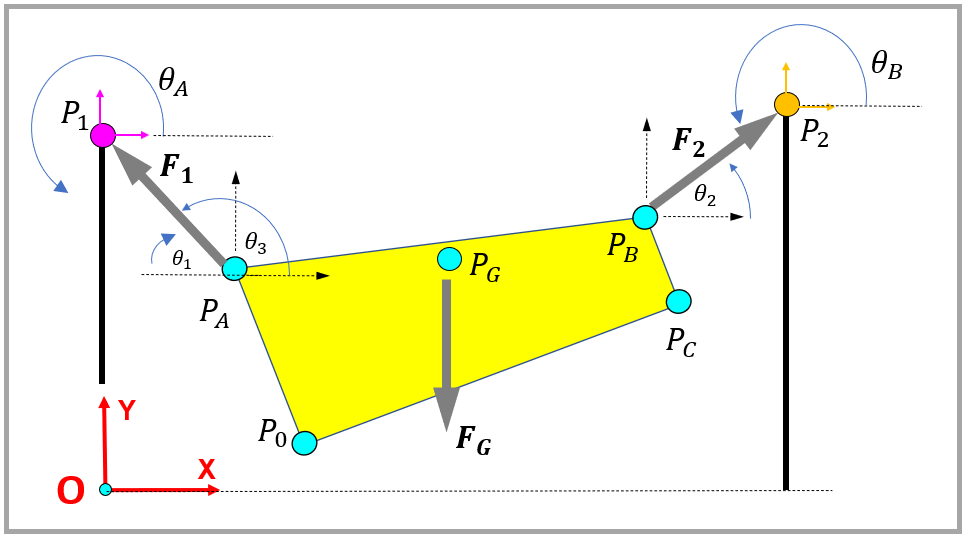

Next, we need to determine the forces $F_1$ and $F_2$ acting on the steel plate.  Recall that these forces are produced by the SPRINGS.  These spring forces can be computed using the formula:

- $F_i \;=k_i \ldotp \Delta L_i$     where   $\Delta L_i =L_i -L_{{i\;}_{\textrm{FREE}} }$

So ? - So for each spring we need to determine:

- The spring's final length $L$

- How much has the spring stretched $\Delta L$ from it's UNstretched length $L_{\textrm{FREE}}$

- The MAGNITUDE of the force that the spring is applying to the steel plate

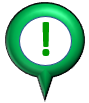**NOTE:**   In MATLAB, if you have a vector $v$ , then you can compute its **norm** $\left|v\right|$ using the [`norm`](matlab:  web(fullfile(docroot, 'matlab/ref/norm.html'))) function, for example:

- 
$$v=\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\left|v\right|=\sqrt{3^2 \;+4^2 }\;=\;5$$


**STEP_1_LEFT :   The Final length of the LEFT spring**

- 
$$L=\left|P_A -P_1 \right|$$


L_final_LEFT_spring = norm(  Final_rel2_W.PA(:) - Points.P1(:)   );

**STEP_2_LEFT :   The stretched length of the LEFT spring**

- 
$$\Delta L=L-L_{\;\textrm{FREE}}$$


disp_LEFT_spring  = L_final_LEFT_spring - Springs.LEFT.free_length;

**STEP_3_LEFT :   Compute the MAGNITUDE of the force exerted by the LEFT spring onto the steel plate**

- 
$$F=k\ldotp \Delta L$$


FORCES.F1_mag = Springs.LEFT.stiffness  * disp_LEFT_spring;

 **YOUR turn: ** Now we need to repeat the above calculations  .... for the **RIGHT** hand side spring.  Follow the "process" demonstrated above, and write the appropriate MATLAB code for the following variables:

- `L_final_RIGHT_spring`

- `disp_RIGHT_spring   `

- `FORCES.F2_mag `

% L_final_RIGHT_spring = 0;
% disp_RIGHT_spring    = 0;
% FORCES.F2_mag        = 0;

 Now Run this section by clicking the button below

## The Force Vectors acting on the Steel Plate

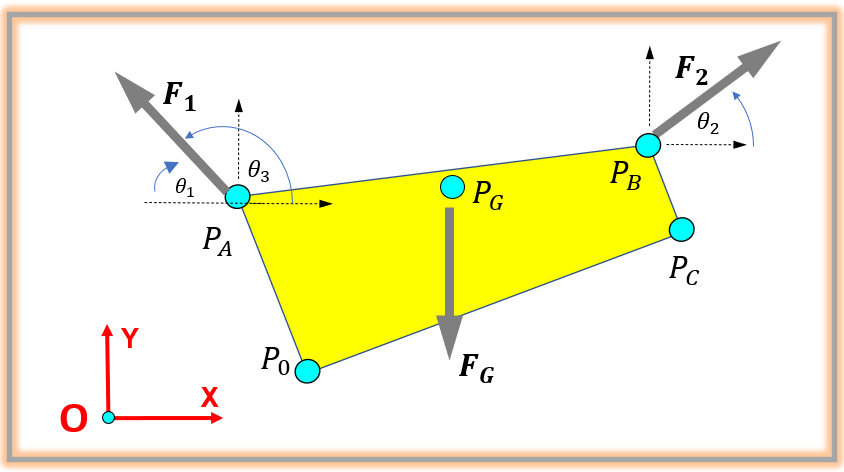

Now that we know the **MAGNITUDES** of the spring forces, we can now construct the **VECTORS** of these corresponding forces. And while we're at it, we'll define the gravity force vector too.  So the 3 force vectors acting on our steel plate are:

- 
$$\vec{F_1 } =\left\lbrack \begin{array}{c}
\;\;\left|F_1 \right|\ldotp \cos \left(\theta_3 \right)\;\;\\
\left|F_1 \right|\ldotp \sin \left(\theta_3 \right)
\end{array}\right\rbrack \;\;\;\;\;,\;\;\;\;\;$$

$$\vec{F_2 } =\left\lbrack \begin{array}{c}
\;\;\left|F_2 \right|\ldotp \cos \left(\theta_2 \right)\;\;\\
\left|F_2 \right|\ldotp \sin \left(\theta_2 \right)
\end{array}\right\rbrack \;\;\;\;\;,\;\;\;\;\vec{F_G } =\left\lbrack \begin{array}{c}
\;\;0\;\;\\
\;-m\ldotp g\;
\end{array}\right\rbrack$$


Here's our force vector $\vec{F_G }$ caused by gravity:

FORCES.G          = [0, -1*env.g*quad_obj.mass];

Now let;s compute $\vec{F_1 }$ and $\vec{F_2 }$

-  **NOTE:**   In MATLAB, there are BOTH radian and degree versions of the standard trig functions, eg:   [`cos()`](matlab:  web(fullfile(docroot, 'matlab/ref/double.cos.html'))) and [`cosd()`](matlab:  web(fullfile(docroot, 'matlab/ref/cosd.html')))  ... so make sure you use the right one !

FORCES.F1         = FORCES.F1_mag * [cosd(Final_rel2_W.theta3_deg),   sind(Final_rel2_W.theta3_deg) ];

 **YOUR turn: **Follow the "process" demonstrated above, and write the appropriate MATLAB code for the following variable:

- `FORCES.F2`

% FORCES.F2       = [0,0];

So what values have we computed so far ?

disp(FORCES)

 Now Run this section by clicking the button below

## Explore the vector Sum of FORCES

Given that our steel plate is in equillibrium ... what do we expect IFFF we sum up all of the (vector) forces acting on the plate ?

- 
$${\vec{F} }_{\textrm{TOTAL}} \;={\vec{F} }_1 \;\;+\;\;{\vec{F} }_2 \;\;\;+\;\;{\vec{F} }_G$$


vec_sum_of_F = FORCES.F1  +  FORCES.F2  +  FORCES.G

We can plot this vector sum using the [`quiver()`](matlab:  web(fullfile(docroot, 'matlab/ref/quiver.html'))) function to draw each of the force vectors

- `quiver( X_start, Y_start, vec_x_dir, vec_y_dir )`

- For a quick tutorial on how to use the [`quiver()`](matlab:  web(fullfile(docroot, 'matlab/ref/quiver.html'))) function, have a look at the script [`bh_PREwork_things.mlx`](matlab:  edit bh_PREwork_things.mlx)

figure;

    % plot a PINK dot at (0,0)
    xy_start_point = [0,0];
    plot(xy_start_point(1), xy_start_point(2), '.m', "MarkerSize", 55); hold("on"); 

    % plot F1
    quiver(xy_start_point(1), xy_start_point(2),  FORCES.F1(1), FORCES.F1(2), 'off', 'r',  "LineWidth",3);   
    
    % plot F2
    xy_start_point = FORCES.F1;
    quiver(xy_start_point(1), xy_start_point(2),  FORCES.F2(1), FORCES.F2(2), 'off', 'g',  "LineWidth",3);  
    
    %plot F3=m.g
    xy_start_point = FORCES.F1 + FORCES.F2;
    quiver(xy_start_point(1),xy_start_point(2),   FORCES.G(1),  FORCES.G(2),  'off',   'b', "LineWidth",3);  
    
        grid("on");
        xlabel("X (Newtons)")
        ylabel("Y (Newtons)")
        title("vector SUM of FORCES");
        legend(["0","F_1", "F_2", "m.g"], "Location", "best")

 Now Run this section by clicking the button below

 Comment on the shape of this vector sum. Particularly comment on whether the three vectors (**F1**, **F2**, and **W**) form a closed polygon.

## Explore the lines of actions of the forces acting on a three-force body

Next, let's draw the steel plate in it's final position .... ***AND*** then let's also draw the force **vectors** acting on the steel plate

## 

### **Draw the Final pose of the steel plate:**

First let's plot the FINAL positions of points $P_0 \;,P_A \;,P_B \;,P_C \;,P_G$ of our steel plate

x_coord_list = [Final_rel2_W.PZERO(1), Final_rel2_W.PA(1), Final_rel2_W.PB(1), Final_rel2_W.PC(1), Final_rel2_W.PZERO(1)];
y_coord_list = [Final_rel2_W.PZERO(2), Final_rel2_W.PA(2), Final_rel2_W.PB(2), Final_rel2_W.PC(2), Final_rel2_W.PZERO(2)];

figure;
   % plot the corner points
   plot(x_coord_list, y_coord_list, '-ko', "LineWidth",2,"MarkerFaceColor","cyan");
        hold on
   % plot the center of mass
   plot(Final_rel2_W.PG(1), Final_rel2_W.PG(2), '-ko', "LineWidth",2,"MarkerFaceColor","cyan");
        grid("on")
        axis("equal")

### **Draw the Force vectors acting on the steel plate:**

Define a scaling factor for drawing our Force vectors - this is just so that we can draw the vectors nicely on the page

a_scale_value = 1.75 * norm(Final_rel2_W.PZERO-Final_rel2_W.PC)

**NOTE:**  When we draw the **Line of Action** of a force vector - we'll use the [`quiver()`](matlab:  web(fullfile(docroot, 'matlab/ref/quiver.html'))) function

- `quiver( X_start, Y_start, vec_x_dir, vec_y_dir )`

- For a quick tutorial on how to use the [`quiver()`](matlab:  web(fullfile(docroot, 'matlab/ref/quiver.html'))) function, have a look at the script [`bh_PREwork_things.mlx`](matlab:  edit bh_PREwork_things.mlx)

Draw the Line of Action for $m\ldotp g$

xy_start_point      = Final_rel2_W.PG;
unit_Force_vector   = FORCES.G/(norm(FORCES.G));
scaled_F_vec        = a_scale_value * unit_Force_vector;

quiver(xy_start_point(1),xy_start_point(2),  scaled_F_vec(1),  scaled_F_vec(2), 'off', 'b-', "LineWidth",1);   
      hold("on"); 
quiver(xy_start_point(1),xy_start_point(2), -scaled_F_vec(1), -scaled_F_vec(2), 'off', 'b--', "LineWidth",1); 

Draw the Line of Action for $F_1$

xy_start_point      = Final_rel2_W.PA;
unit_Force_vector   = FORCES.F1/(norm(FORCES.F1));
scaled_F_vec        = a_scale_value * unit_Force_vector;

quiver(xy_start_point(1),xy_start_point(2),  scaled_F_vec(1),  scaled_F_vec(2), 'off', 'r-', "LineWidth",1);   
      hold("on"); 
quiver(xy_start_point(1),xy_start_point(2), -scaled_F_vec(1), -scaled_F_vec(2), 'off', 'r--', "LineWidth",1); 

 **YOUR turn: ** Review the code above ... and then write the appropriate MATLAB code for Drawing the Line of Action for $F_2$

% xy_start_point      = ;
% unit_Force_vector   = ;
% scaled_F_vec        = ;
% quiver(xy_start_point(1),xy_start_point(2),  scaled_F_vec(1),  scaled_F_vec(2), 'off', 'g-', "LineWidth",1);   
%       hold("on"); 
% quiver(xy_start_point(1),xy_start_point(2), -scaled_F_vec(1), -scaled_F_vec(2), 'off', 'g--', "LineWidth",1); 

 Now Run this section by clicking the button below

  Comment on your diagram, particularly in regard to the intersection or otherwise of the lines of action of these three forces.

# Next Steps:

If you'd like to know more about MATLAB or Simulink, please check out the FREE Self Paced training courses at [**MATLAB Academy**](https://matlabacademy.mathworks.com/)